## 1) Visualizing parameterized curves in the plane and in space

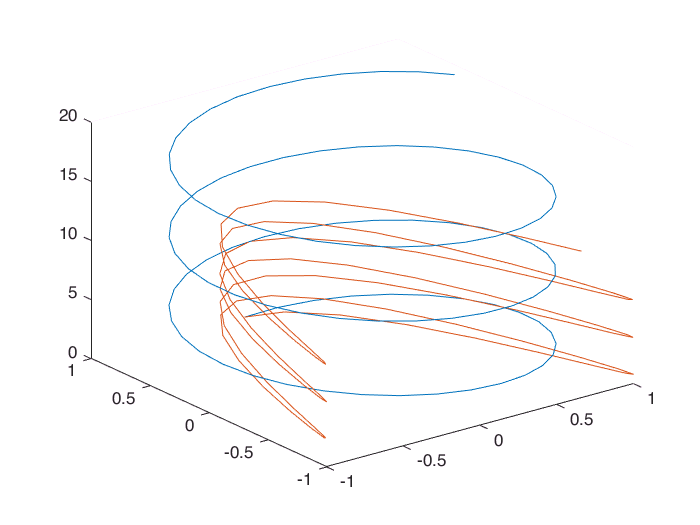

t = 0:20/100:20;
x = sin(t);
y = cos(t);
figure
plot3(x, y, t)
hold on
y = cos(2*t);
plot3(x, y, t/2)

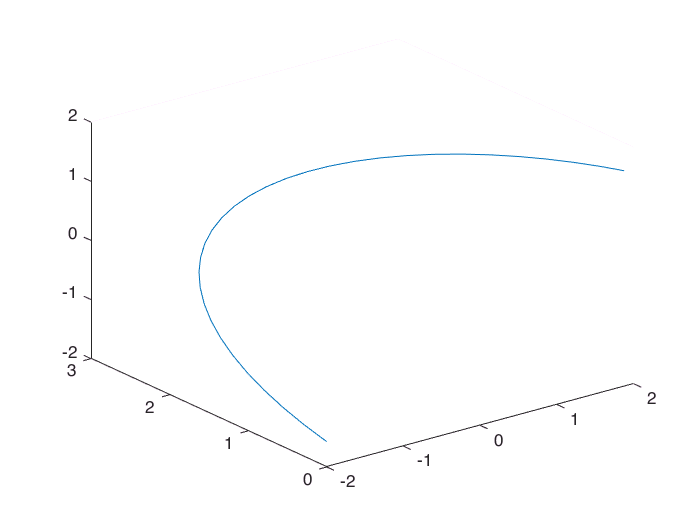

t = (-pi/2):.1:(pi/2);
x = 2*sin(t);
y = 3*cos(t);
figure
plot3(x, y, t)

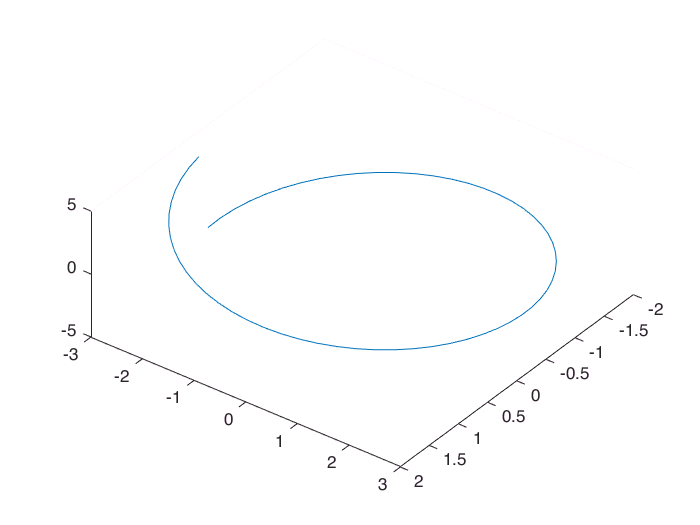

t = (-pi):.1:(pi);
x = 2*sin(t);
y = 3*cos(t);
figure
plot3(x, y, t)

view([127.07 59.71])

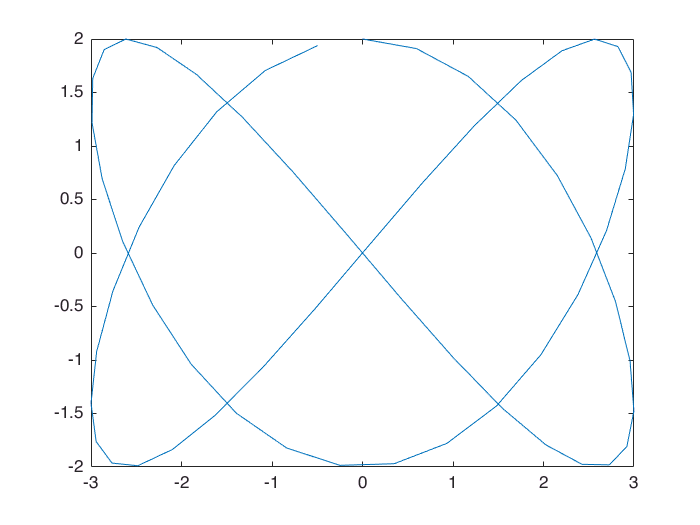

t = 0:.1:2*pi;
x = 3*sin(2*t);
y = 2*cos(3*t);
figure
plot(x, y)

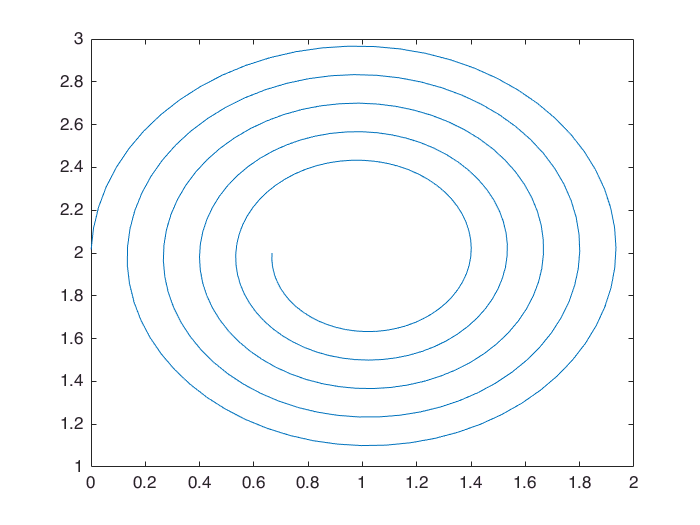

t = (5*pi):.1:(15*pi);
x = 1+t./(15*pi).*cos(t);
y = 2+t./(15*pi).*sin(t);
figure
plot(x, y)

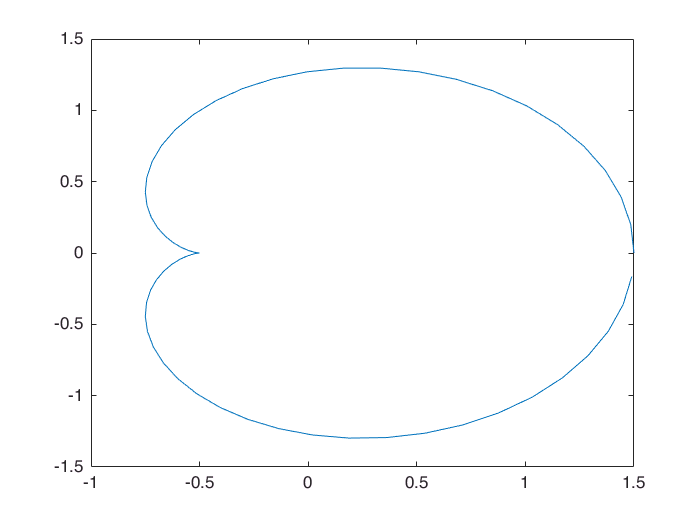

t = 0:.1:(2*pi);
x = cos(t)+cos(2*t)/2;
y = sin(t)+sin(2*t)/2;
figure
plot(x, y)

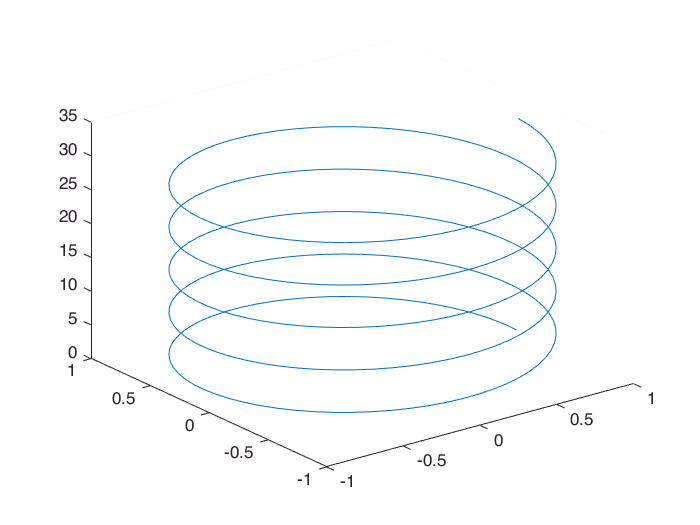

t = 0:.1:(10*pi);
x = cos(t);
y = sin(t);
z = t;
figure
plot3(x, y, z)

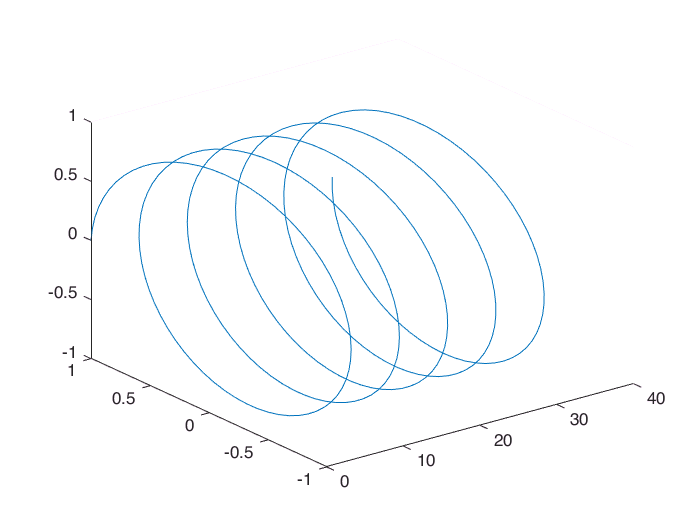

t = 0:.1:(10*pi);
y = cos(t);
z = sin(t);
x = t;
figure
plot3(x, y, z)

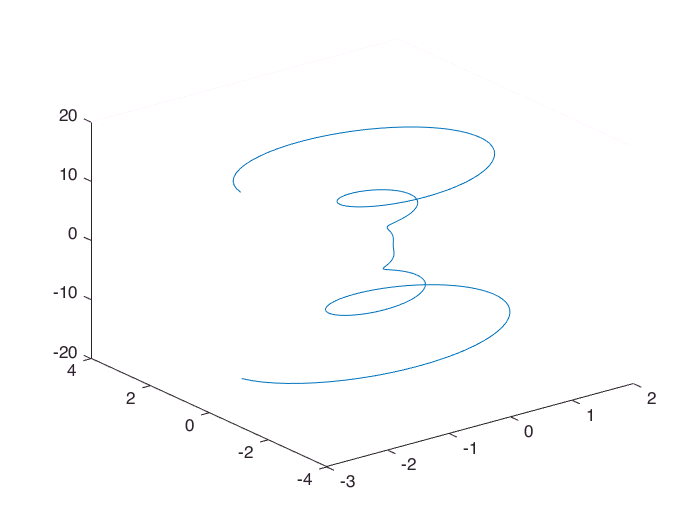

t = -5*pi:.1:5*pi;
x = 1/100*t.^2.*cos(t);
y = 1/100*t.^2.*sin(t);
z = t;
figure
plot3(x, y, z)

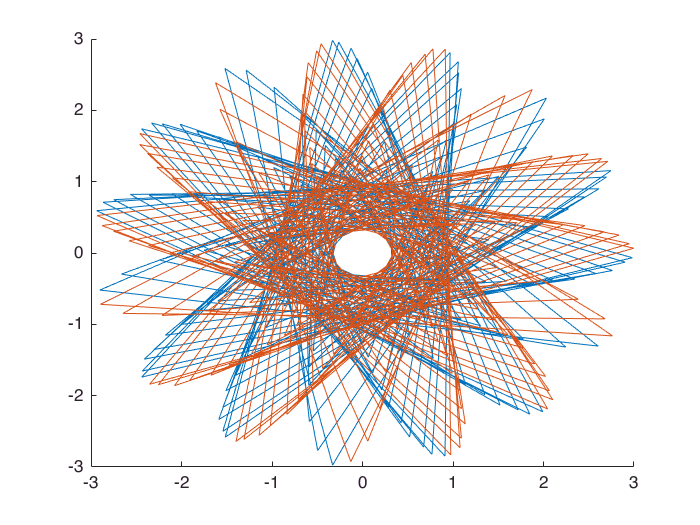

t = -5*pi:.1:5*pi;
x = (2+sin(t)).*cos(25*t);
y = (2+sin(t)).*sin(25*t);
z = 2*cos(t);
figure
hold on
plot3(x, y, z)
z = 3*cos(t);
plot3(x, y, z)

## 2) Visualizing tangent and velocity

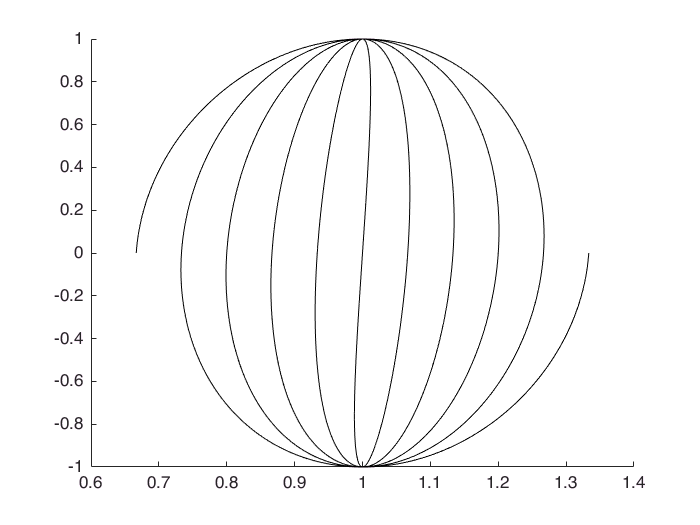

figure
h = animatedline;
numpoints = 10000;

t = linspace(-5*pi,5*pi,numpoints);
x = 1+t./(15*pi).*cos(t);
y = sin(t);
u = gradient(x);
v = gradient(y);
a = tic; % start timer
for k = 1:numpoints
    addpoints(h,x(k),y(k))
    b = toc(a); % check timer
    if b > (1/10)
        drawnow % update screen every 1/30 seconds
        a = tic; % reset timer after updating
    end
end

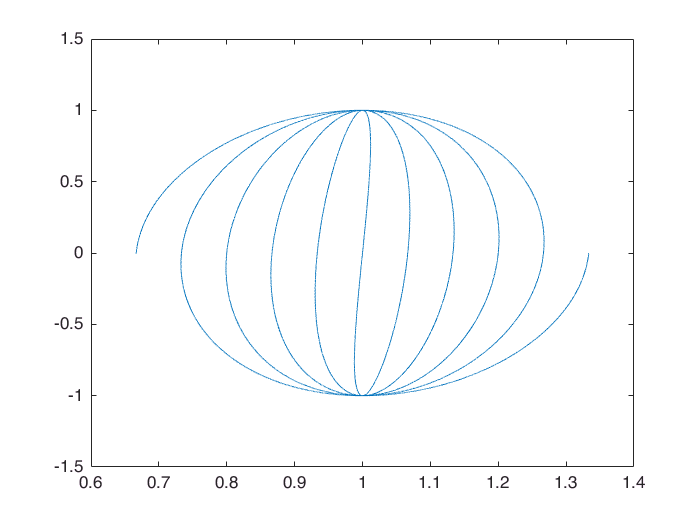

drawnow % draw final frame
quiver(x,y,u,v, .1)

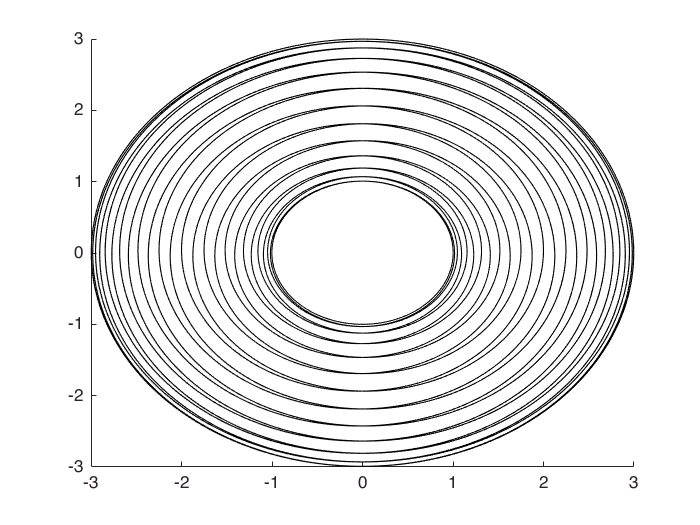

figure
h = animatedline;
numpoints = 10000;

t = linspace(-5*pi,5*pi,numpoints);
x = (2+sin(t)).*cos(25*t);
y = (2+sin(t)).*sin(25*t);
z = 2*cos(t);

a = tic; % start timer
for k = 1:numpoints
    addpoints(h, x(k),y(k), z(k))
    b = toc(a); % check timer
    if b > (1/1000)
        drawnow % update screen every 1/30 seconds
        a = tic; % reset timer after updating
    end
end

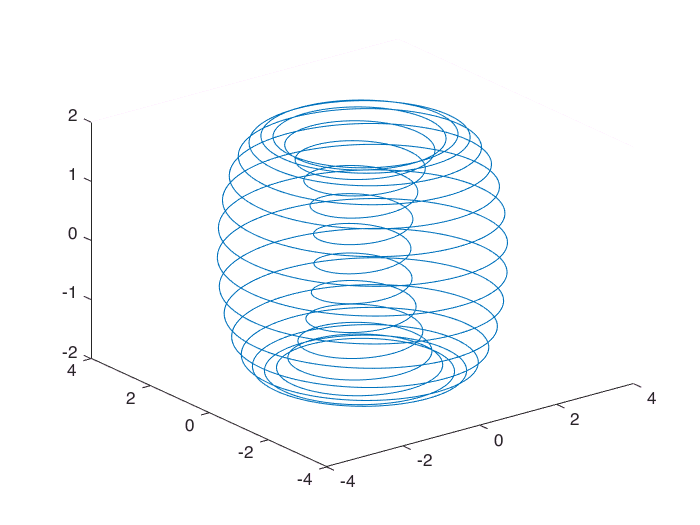

drawnow % draw final frame
figure
plot3(x, y, z)

## 4) Visualizing families of parameterized curves in the plane

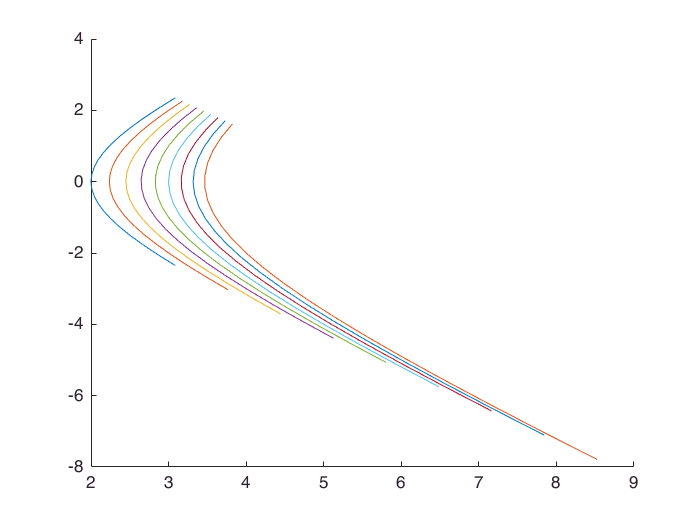

t = -1:.1:1;
a = -1:.1:1;

figure
hold on
for a=1:.25:3
    x = exp(t)+a.*exp(-t);
y = exp(t)-a.*exp(-t);
    plot(x, y)
end

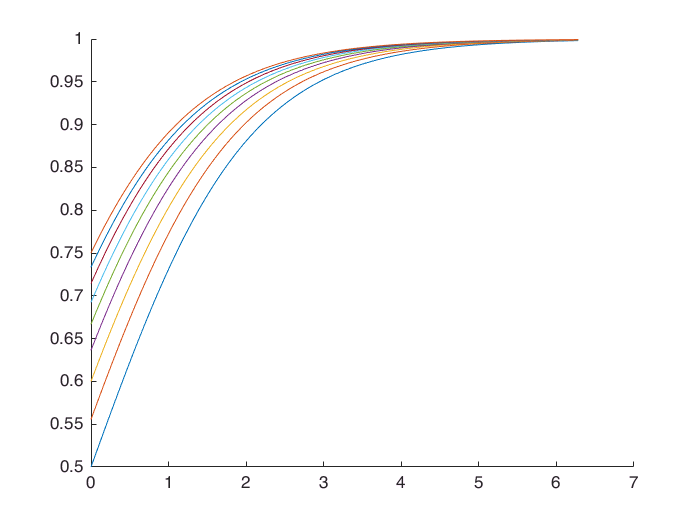

t = linspace(0,2*pi, 1000);
figure
hold on
for a=1:.25:3
    x = t;
    y = a.*exp(t)./(1+a.*exp(t));
    plot(x, y)
end

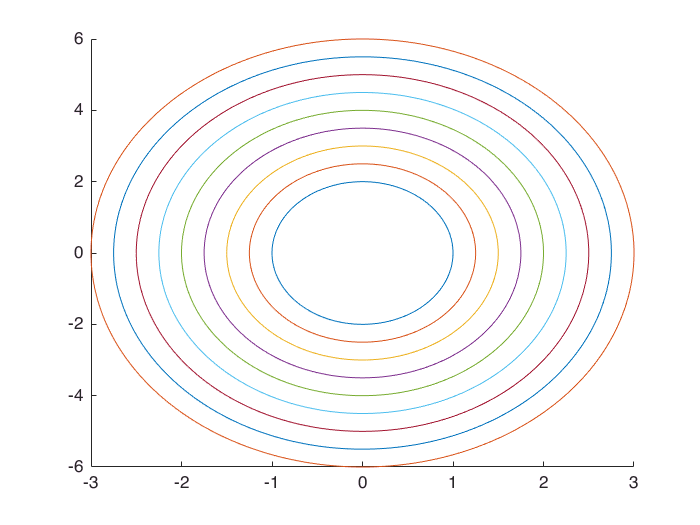

t = linspace(0,2*pi, 1000);
a = linspace(1,3, 1000);
figure
hold on
for a=1:.25:3
    x = a.*cos(t);
    y = 2.*a.*sin(t);
    plot(x, y)
end

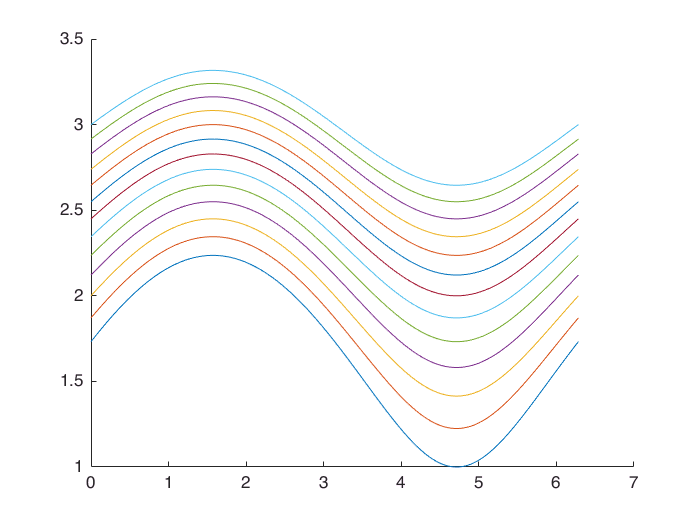

t = linspace(0,2*pi, 1000);
figure
hold on
for a=2:.25:5
    x = t;
    y = sqrt(2.*a+2*sin(t)-1);
    plot(x, y)
end

## 5) Vector Fields and Differential Equation

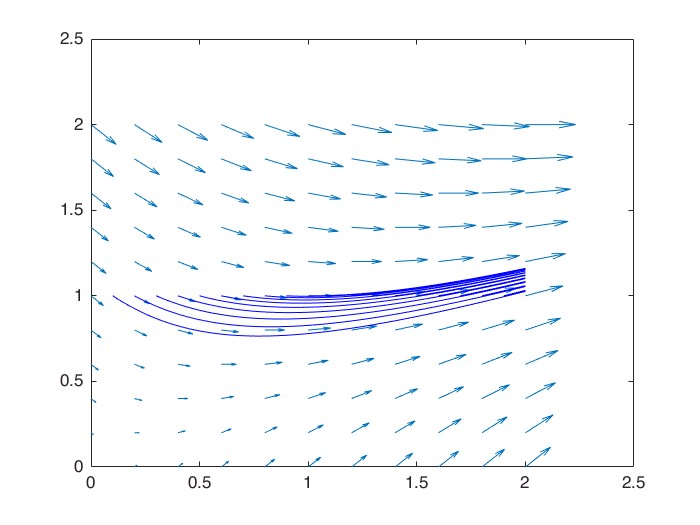

[x,y] = meshgrid(0:0.2:2,0:0.2:2);
u = x+y;
v = x-y;

figure
quiver(x,y,u,v)
startx = 0.1:0.1:2;
starty = ones(size(startx));
streamline(x,y,u,v,startx,starty)

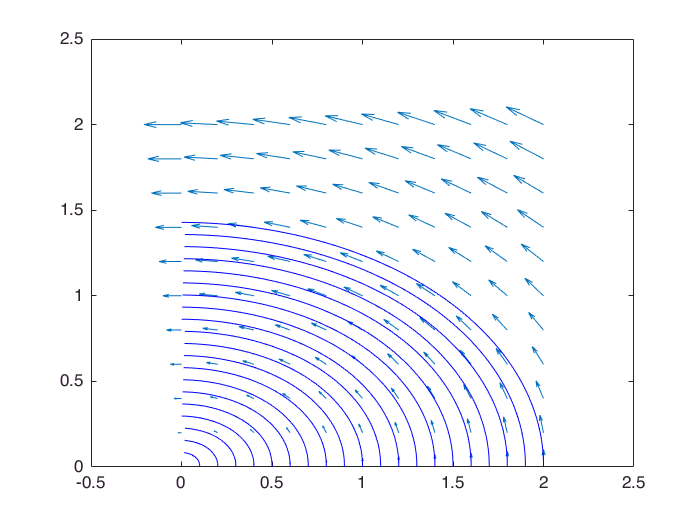

[x,y] = meshgrid(0:0.2:2,0:0.2:2);
u = -2*y;
v = x;

figure
quiver(x,y,u,v)
startx = 0.1:0.1:2;
starty = zeros(size(startx));
streamline(x,y,u,v,startx,starty)

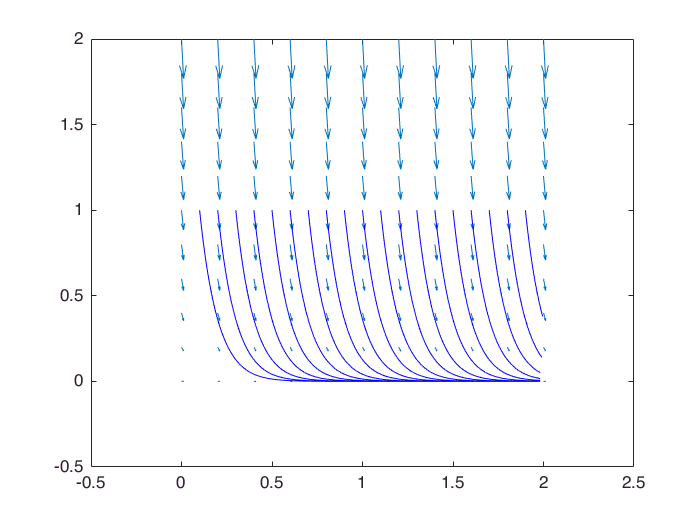

[x,y] = meshgrid(0:0.2:2,0:0.2:2);
u = ones(11, 11);
v = y-y^2;

figure
quiver(x,y,u,v)
startx = 0.1:0.1:2;
starty = ones(size(startx));
streamline(x,y,u,v,startx,starty)

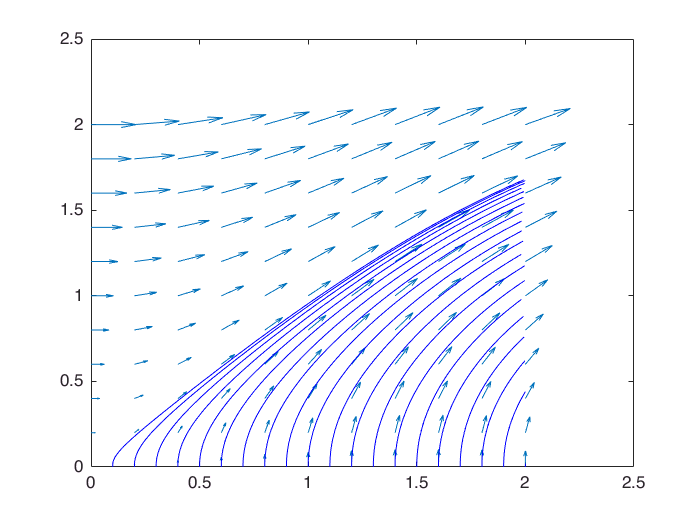

[x,y] = meshgrid(0:0.2:2,0:0.2:2);
u = y;
v = sin(x);

%figure
quiver(x,y,u,v)

startx = 0.1:0.1:2;
starty = zeros(size(startx));
streamline(x,y,u,v,startx,starty)

## 6) Parametric Curve in Space

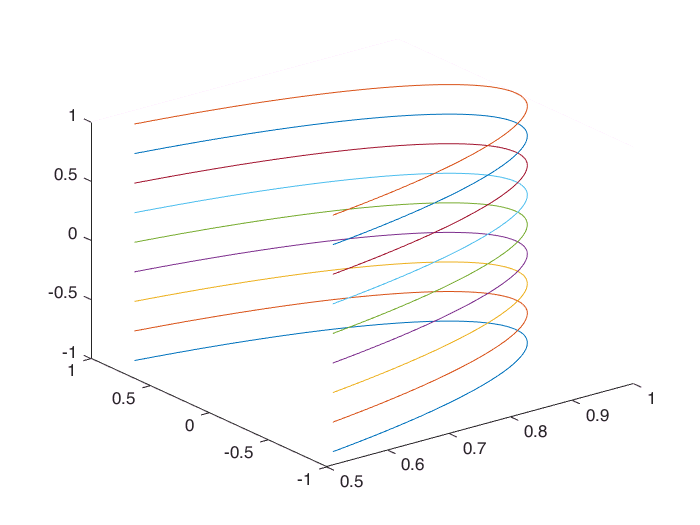

t = linspace(-1, 1, 100);
figure
for a=-1:.25:1
    x = cos(t);
    y = sin(t);
    z(1, 1:100) = a;
    plot3(x, y, z)
    hold on
end

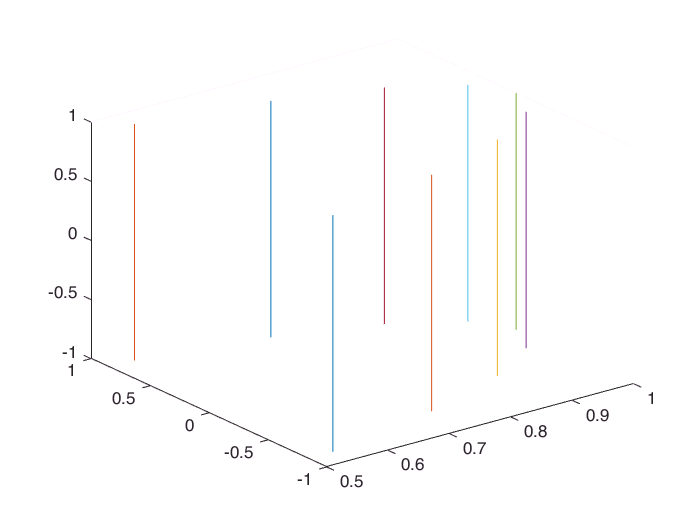

a = linspace(-1, 1, 100);
figure
for t=-1:.25:1
    x(1, 1:100) = cos(t);
    y(1, 1:100) = sin(t);
    z = a;
    plot3(x, y, z)
    hold on
end

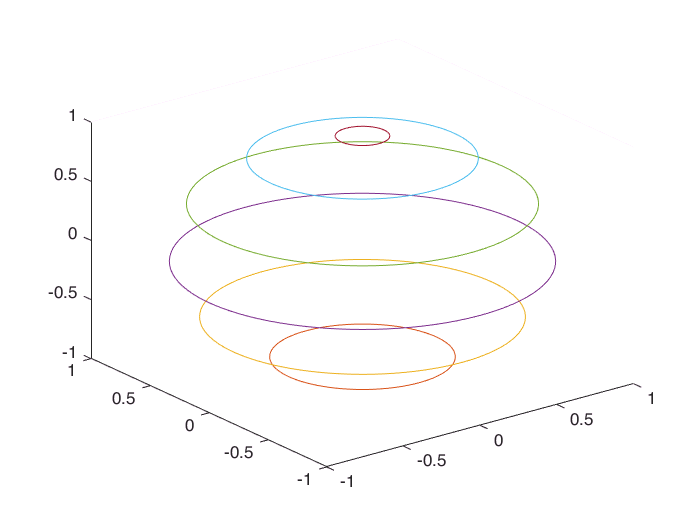

t = linspace(0, 2*pi, 100);
figure
for a=-pi/2:.5:pi/2
    x = cos(t)*cos(a);
    y = sin(t)*cos(a);
    z(1, 1:100) = sin(a);
    plot3(x, y, z)
    hold on
end

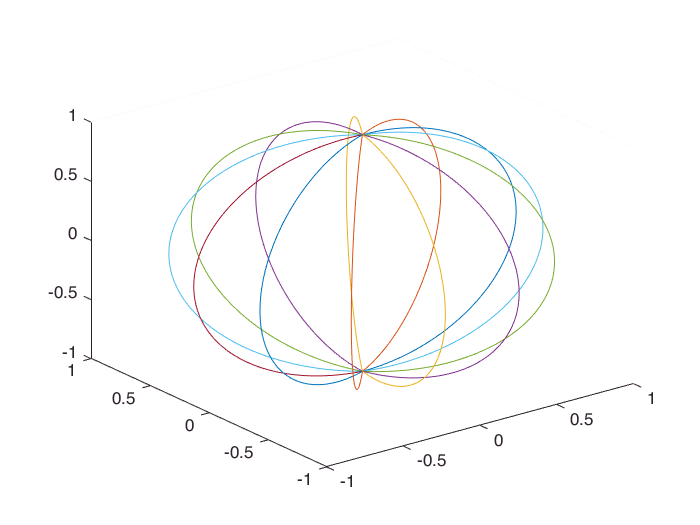

a = linspace(-pi/2, pi/2, 100);
figure
for t=0:.5:2*pi
    x = cos(t)*cos(a);
    y = sin(t)*cos(a);
    z(1, 1:100) = sin(a);
    plot3(x, y, z)
    hold on
end

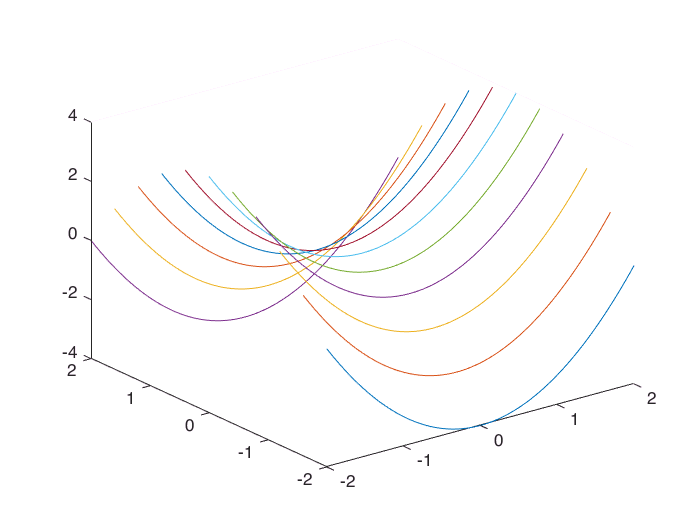

t = linspace(-2, 2, 100);
figure
for a=-2:.4:2
    x = t;
    A(1, 1:100) = a;
    y = A;
    z = t.^2-a.^2;
    plot3(x, y, z)
    hold on
end

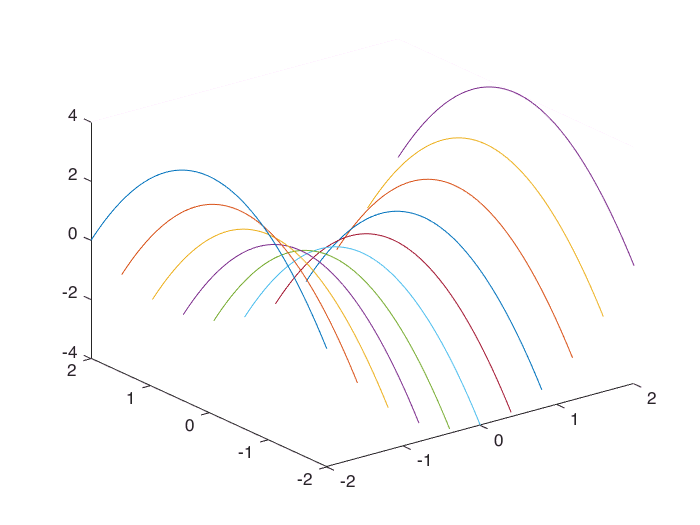

a = linspace(-2, 2, 100);
figure
for t=-2:.4:2
    T(1, 1:100) = t;
    x = T;
    y = a;
    z = T.^2-a.^2;
    plot3(x, y, z)
    hold on
end

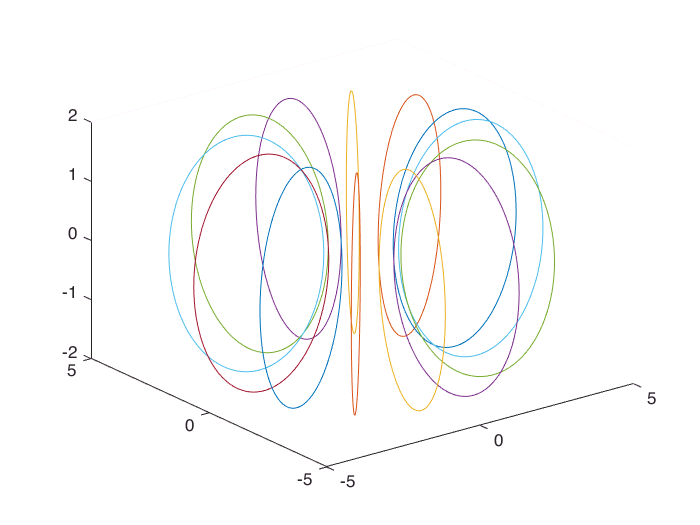

t = linspace(0, 2*pi, 100);
figure
for a=0:.5:2*pi
    x = (3+2*cos(t)).*cos(a);
    y = (3+2*cos(t)).*sin(a);
    z = 2*sin(t);
    plot3(x, y, z)
    hold on
end

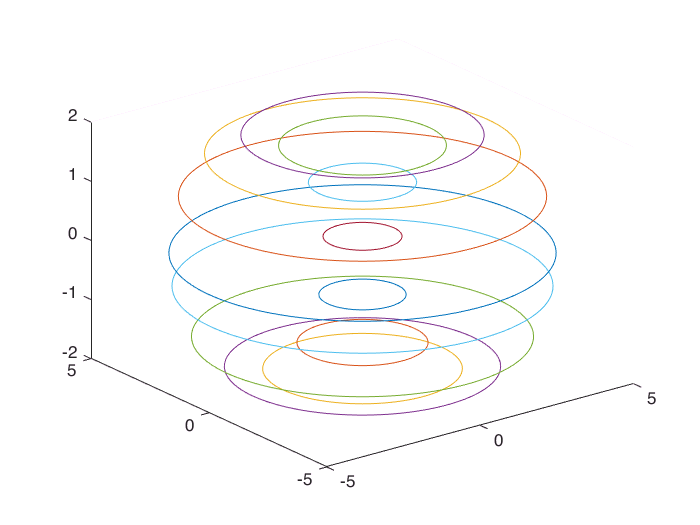

a = linspace(0, 2*pi, 100);
figure
for t=0:.5:2*pi
    x = (3+2*cos(t)).*cos(a);
    y = (3+2*cos(t)).*sin(a);
    z(1, 1:100) = 2*sin(t);
    plot3(x, y, z)
    hold on
end